# Side-By-Side Tables

This example shows how to arrange tables side-by-side on a page.

The example places each table in adjacent entries of an invisible table, which is a table with no borders or colors. The invisible table causes the inserted tables to appear to be side-by-side.

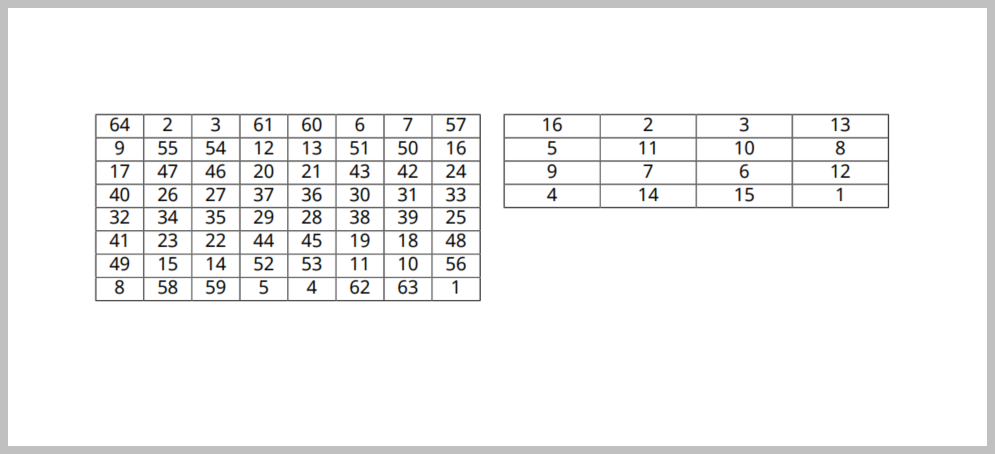

Import the DOM and Report API packages so you do not have to use long, fully-qualified class names. Also, create a Report object.

import mlreportgen.dom.*
import mlreportgen.report.*

% To create a Word report, change the output type from "pdf" to "docx". 
% To create an HTML report, change "pdf” to “html” or "html-file" for a 
% multifile or single-file report, respectively.
rpt = Report('myreport','pdf');

Create two Table objects, table1 and table2, to hold magic squares data. Set the width of these tables to be 100% to fit in the invisible table cells created below. Also, specify the styles for the table borders, row separators, and column separators.

tableStyle = { ...
    Width('100%'), ...
    Border('solid','black','1px'), ...
    ColSep('solid','black','1px'), ...
    RowSep('solid','black','1px') ...
    };

table1 = Table(magic(8));
table1.TableEntriesHAlign = 'center';
table1.Style = tableStyle;

table2 = Table(magic(4));
table2.TableEntriesHAlign = 'center';
table2.Style = tableStyle;

Insert the tables in the only row of a 1x3, invisible layout table (lo_table). A table is considered invisible when the borders are not defined for the table nor any of its table entries.

lo_table = Table({table1,' ',table2});

Specify the width of the layout table entries to fit the magic squares tables.

lo_table.entry(1,1).Style = {Width('3.2in')};
lo_table.entry(1,2).Style = {Width('.2in')};
lo_table.entry(1,3).Style = {Width('3.2in')};

Set the layout table width so it spans the width of the page between the margins. Set ResizeToFitContents to false so the layout table columns are not resized and instead the specified widths are used.

lo_table.Style = {Width('100%'), ResizeToFitContents(false)};

Generate and display the report.

add(rpt, lo_table);
close(rpt);
rptview(rpt);

*Copyright 2018 The MathWorks, Inc.*